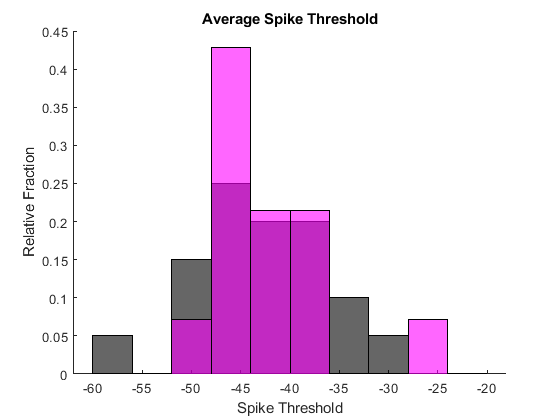

ups = grabFromFilter('UP Cells');
downs = grabFromFilter('DOWN Cells');


%choose which protocols to look at
priorityOrder_1 = {'Ramp'}; %first field name shosuld be one of these. Priority is in given order
priorityOrder_2 = {'_ff'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'CurrentClamp', 'PotassiumSpikes'};
cantHave_1 = [];
cantHave_2 = {'Cesium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates

upAvgThresholds = [];
for i = 1:size(ups)
    struct_i = ups{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    upAvgThresholds = [upAvgThresholds, loc.Analysis_Results.averageThreshold];
end

downAvgThresholds = [];
for i = 1:size(downs)
    struct_i = downs{i, 2};
    [loc, pass] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass
        continue
    end
    downAvgThresholds = [downAvgThresholds, loc.Analysis_Results.averageThreshold];
end

edgs = [-60:4:-20];
figure()
title('Average Spike Threshold')
hold on
histogram(upAvgThresholds, 'FaceColor', 'k', 'BinEdges', edgs, 'Normalization', 'probability');
histogram(downAvgThresholds, 'FaceColor', 'm', 'BinEdges', edgs, 'Normalization', 'probability');
xlabel('Spike Threshold')
ylabel('Relative Fraction')

ranksum(upAvgThresholds, downAvgThresholds)

ans = 0.6366


SEM = std(thresholds)/sqrt(length(thresholds));               % Standard Error
ts = tinv([0.025  0.975],numel(thresholds)-1);      % T-Score
CI = mean(thresholds) + ts*SEM;                      % Confidence Intervals